# Supply Chain Network Simulator

Designing the Supply Chain Network

clear all
close all
clc

rng(7)

caseNum = 2;

if caseNum == 1
    numOfChains = 2;            % Number of parallel chains
    numOfInventories = 3;       % Number of inventories in each chain
    matFile = 'Results/Case1/gridSearchCompleteDesignResults.mat';
elseif caseNum == 2
    numOfChains = 3;            % Number of parallel chains
    numOfInventories = 4;       % Number of inventories in each chain
    matFile = 'Results/Case2/gridSearchCompleteDesignResults.mat';
elseif caseNum == 3
    numOfChains = 4;            % Number of parallel chains
    numOfInventories = 5;       % Number of inventories in each chain
    matFile = 'Results/Case3/gridSearchCompleteDesignResults.mat';
end

% Create Network
netId = 1;               % Supply chain network ID
net = Network(netId, numOfChains, numOfInventories);

Started creating the supply chain network.
Started creating chain 1
Finished creating a chain...
Started creating chain 2
Finished creating a chain...
Started creating chain 3
Finished creating a chain...
Finished creating the supply chain network.


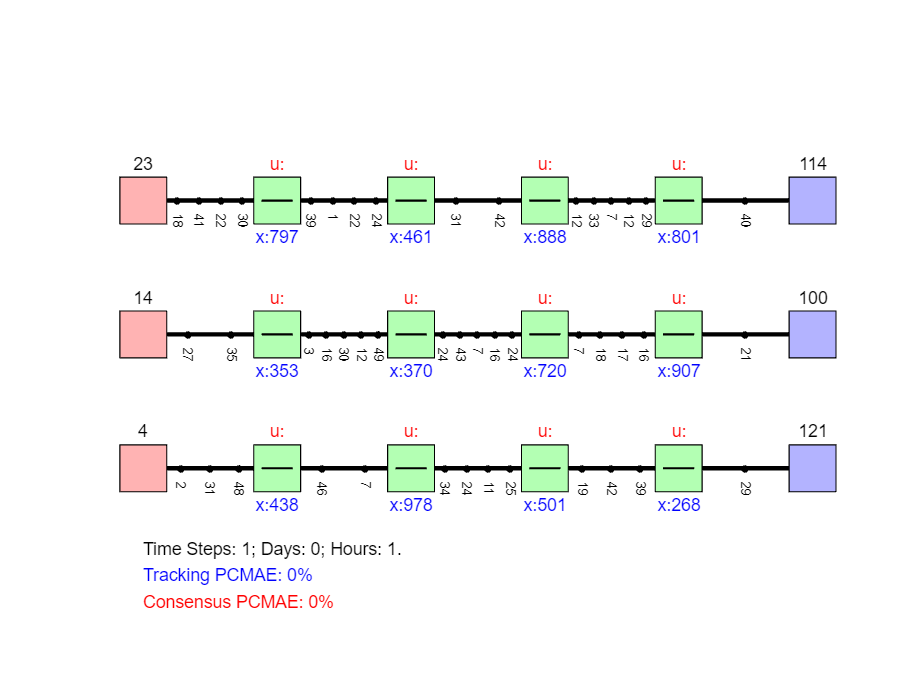


% SCN setup and the initial condition
figNum = 1;
figure(figNum);
hold on; axis equal; axis off;
net.draw(1);


tMax = 24*30 % 4 weeks

tMax = 720

saveMode = 3; % 1 FigSave, 2 vidSave, 3 display


% Grid Search Functions (Execute this seperately as it takes time)
% search input parameters: pVal, deltaCostCoef, gammaCostCoef, comCostLimit
% search output metrics: LNorm, KNorm, GammaTilde, KLinks
% net.gridSearchCompleteDesign(folderName)
% Selecting best parameters that optimize the objective J:
% J = d1 * LNormVal + d2 * KNormVal + d3 * gammaTildeVal + d4 * NumOfLinks
d1 = 1;
d2 = -10; %-10
d3 = 1;
d4 = 1;
[pVal, deltaCostCoef, gammaCostCoef, comCostLimit, KLinks] = net.findBestParameters(matFile,d1,d2,d3,d4) 

pVal = 10

deltaCostCoef = 1000000

gammaCostCoef = 1

comCostLimit = 0.1000

KLinks = 82


pVal = 3.1623

pVal = 3.1623

deltaCostCoef = 0.0010

deltaCostCoef = 1.0000e-03

gammaCostCoef = 100.0000

gammaCostCoef = 100

comCostLimit = 0.1000

comCostLimit = 0.1000


save(['tempNet',num2str(caseNum)])
perfData.cumVals = [];
perfData.conHist = [];
perfData.traHist = [];
perfData.caseName{1} = 'CaseNames';
save('caseNum.mat','caseNum','perfData')

Steady state control: K = 0, L = 0

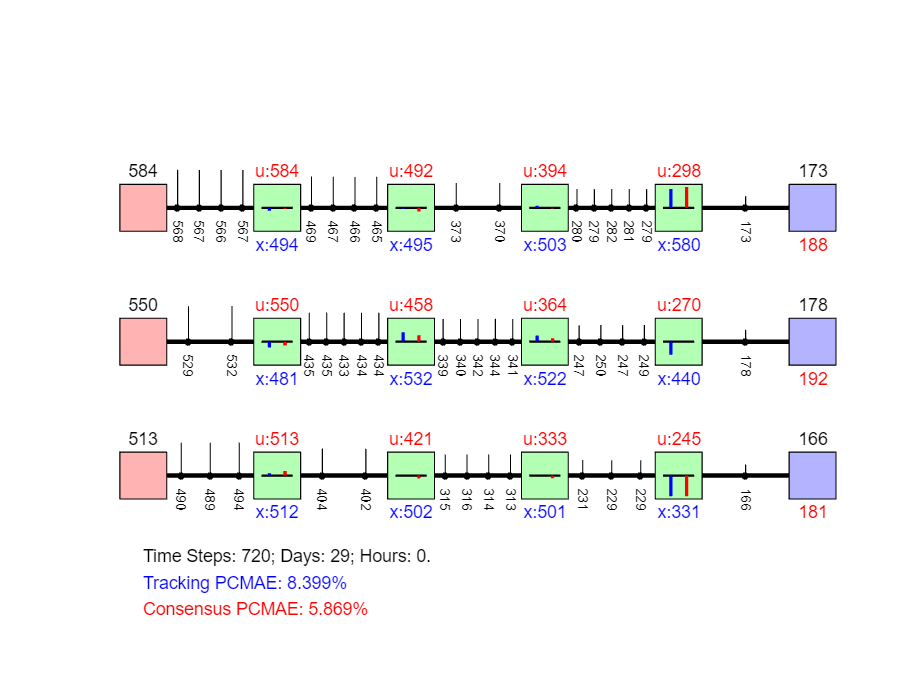

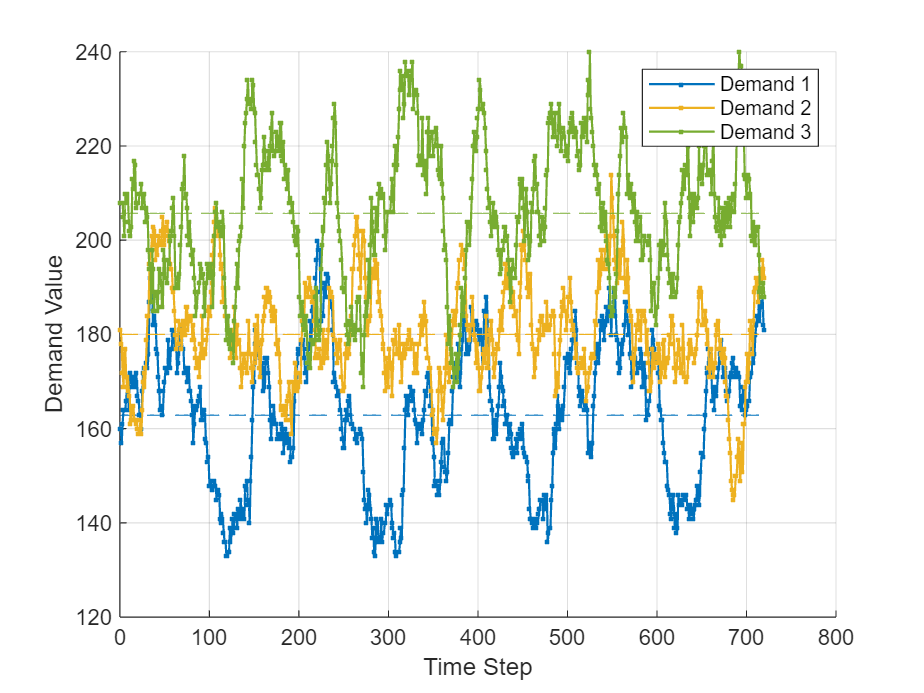

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'Steady';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    net.chains{i}.LLocal = 0*net.chains{i}.LLocal;
end
net.chains{1}.LLocal;
net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();


% Communication topology of the arbitrarily global controllers
% figNum = figNum + 1;
% figure(figNum); 
% hold on; axis equal; axis off;
% net.plotConnections(net.adjMat);

% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end

    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);

    % % % Performance plot
    figNum = figNum + 1;
    f = figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
    close(f);

    % % Performance plot
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotDemandProfiles();
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'SSC';
save('caseNum.mat','caseNum','perfData')

Strict local control: K = 0

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'NullGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    pVal = NaN;
    deltaCostCoef = NaN;
    net.chains{i}.localControlDesign(pVal,deltaCostCoef);
end
net.chains{1}.LLocal

ans =    -0.0549   -0.0350   -0.0208   -0.0166   -0.0599   -0.0720   -0.0837   -0.0372   -0.0422   -0.0229   -0.0249   -0.0268   -0.0288   -0.0180   -0.0194   -0.0212
    0.3612   -0.0532   -0.0238   -0.0199    0.4087    0.1051    0.0248   -0.0590   -0.0692   -0.0260   -0.0283   -0.0309   -0.0368   -0.0211   -0.0224   -0.0241
    0.0157    0.3208   -0.0464   -0.0381    0.0189    0.0140    0.0091    0.3584    0.1017   -0.0505   -0.0551   -0.0612   -0.0732   -0.0402   -0.0426   -0.0459
   -0.0001    0.0007    0.2913   -0.1274    0.0008    0.0009    0.0010    0.0025    0.0021    0.3330    0.0752    0.0152    0.0076   -0.1331   -0.1426   -0.1528


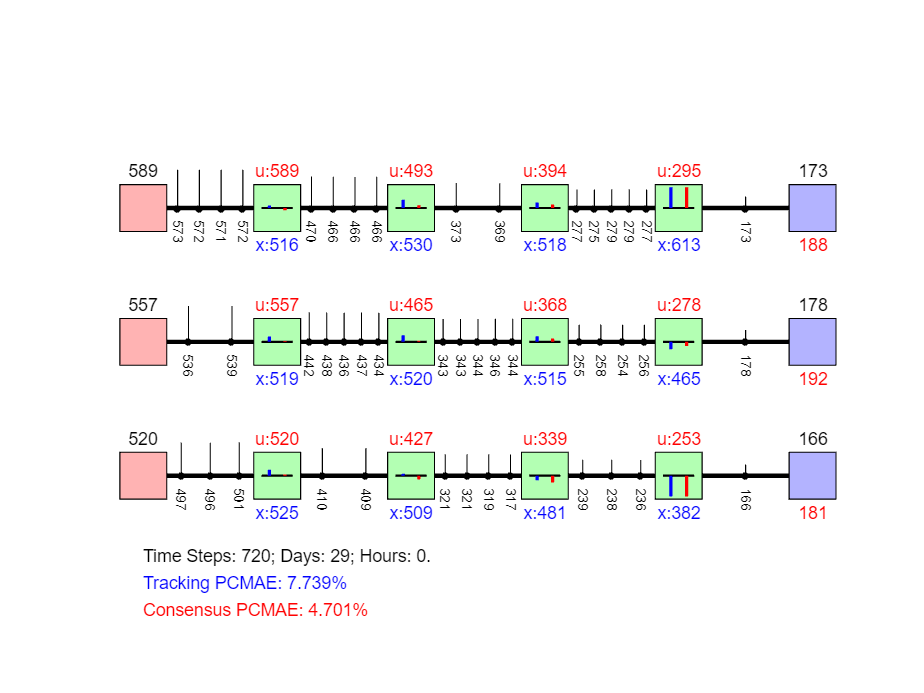

net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();


% Communication topology of the arbitrarily global controllers
% figNum = figNum + 1;
% figure(figNum);
% hold on; axis equal; axis off;
% net.plotConnections(net.adjMat);

% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end

    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);

    % % Performance plot
    figNum = figNum + 1;
    f = figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
    close(f);
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'SLC';
save('caseNum.mat','caseNum','perfData')

Distributed Control with Hard Graph 

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'SoftGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

isSoft = 0;

% Grid Search Functions (Execute this seperately as it takes time)
% search input parameters: pVal, deltaCostCoef, gammaCostCoef, comCostLimit
% search output metrics: LNorm, KNorm, GammaTilde, KLinks
% net.gridSearchCompleteDesign(folderName)

% Selecting best parameters that optimize the objective J:
% J = d1 * LNormVal + d2 * KNormVal + d3 * gammaTildeVal + d4 * NumOfLinks
% d1 = 0;
% d2 = -1; %-10
% d3 = 1;
% d4 = 1;
% [pVal, deltaCostCoef, gammaCostCoef, comCostLimit, KLinks] = net.findBestParameters(matFile,d1,d2,d3,d4) 

%% Applying the found best parameters to design the local and global controllers
% Local controller design
totalStatusLocal = 1;
totalLNorm = 0;
for i = 1:1:net.numOfChains
    [statusLocal, ~, ~, LNormVal, ~, ~] = net.chains{i}.localControlDesign(pVal, deltaCostCoef);
    if ~statusLocal
        totalStatusLocal = 0;
        break;
    else
        totalLNorm = totalLNorm + LNormVal;
    end
end
totalStatusLocal

totalStatusLocal = 1

totalLNorm = totalLNorm / net.numOfChains

totalLNorm = 4.5741

% Global controller design
if totalStatusLocal
    [statusGlobal, gammaTildeVal, ~, ~, KNormVal] = net.globalControlDesign(gammaCostCoef,comCostLimit,isSoft)
end

statusGlobal = logical
   1


gammaTildeVal = 228.6456

KNormVal = 0.0226

net.setAdjointMatrixAndNeighborsAndControllers(); % Load Graph, neighbors and controllers from KVal

% Optimizally designed local and global controllers:
net.chains{1}.LLocal

ans =    -0.6518   -0.7456   -0.7984   -0.6494   -0.7257   -0.7527   -0.7019   -0.8299   -0.8792   -0.8876   -0.9668   -1.0198   -1.0977   -0.7216   -0.8017   -0.8914
    0.0267   -0.4627   -0.4490   -0.3663    0.0349   -0.1425   -0.2180   -0.5155   -0.5288   -0.4996   -0.5397   -0.5870   -0.6045   -0.4068   -0.4521   -0.5061
   -0.2213   -0.1216   -0.4734   -0.3790   -0.2468   -0.2476   -0.2536   -0.1321   -0.2420   -0.5265   -0.5693   -0.6098   -0.5940   -0.4211   -0.4686   -0.5133
   -0.0961   -0.1238    0.0437   -0.3130   -0.1073   -0.1042   -0.0998   -0.1386   -0.1387    0.0534   -0.0902   -0.1610   -0.1933   -0.3478   -0.3873   -0.3968


net.KGlobal

ans =          0         0         0         0         0         0         0         0         0         0         0         0
    0.0226         0         0         0         0         0         0         0         0         0         0         0
         0    0.0226         0         0         0         0         0         0         0         0         0         0
         0         0    0.0226         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0001         0         0         0    0.0152         0         0         0         0         0         0         0
         0   -0.0001         0         0         0    0.0152         0         0         0         0         0         0
         0         0   -0.0001         0         0         0    0.0152         0         0         0         0         0
         0         0      

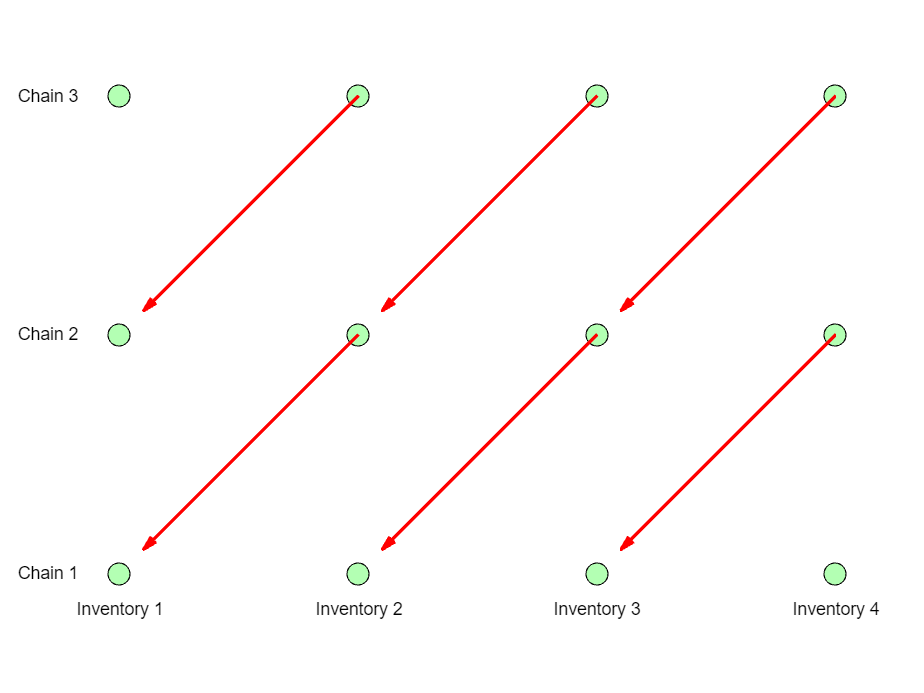


% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

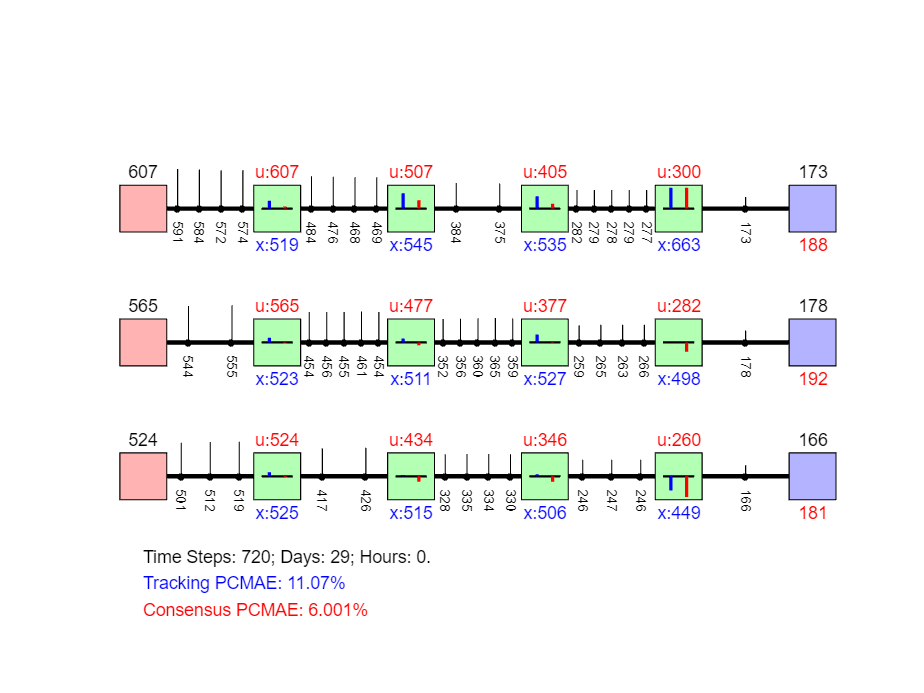


% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % % Performance plot
    figNum = figNum + 1;
    f = figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
    close(f);
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'DHC';
save('caseNum.mat','caseNum','perfData')

Distributed Control with Soft Graph

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'SoftGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

isSoft = 1;

% Grid Search Functions (Execute this seperately as it takes time)
% search input parameters: pVal, deltaCostCoef, gammaCostCoef, comCostLimit
% search output metrics: LNorm, KNorm, GammaTilde, KLinks
% net.gridSearchCompleteDesign(folderName)

% Selecting best parameters that optimize the objective J:
% J = d1 * LNormVal + d2 * KNormVal + d3 * gammaTildeVal + d4 * NumOfLinks
% d1 = 0;
% d2 = -1; %-10
% d3 = 1;
% d4 = 1;
% [pVal, deltaCostCoef, gammaCostCoef, comCostLimit, KLinks] = net.findBestParameters(matFile,d1,d2,d3,d4) 

%% Applying the found best parameters to design the local and global controllers
% Local controller design
totalStatusLocal = 1;
totalLNorm = 0;
for i = 1:1:net.numOfChains
    [statusLocal, ~, ~, LNormVal, ~, ~] = net.chains{i}.localControlDesign(pVal, deltaCostCoef);
    if ~statusLocal
        totalStatusLocal = 0;
        break;
    else
        totalLNorm = totalLNorm + LNormVal;
    end
end
totalStatusLocal

totalStatusLocal = 1

totalLNorm = totalLNorm / net.numOfChains

totalLNorm = 4.5741

% Global controller design
if totalStatusLocal
    [statusGlobal, gammaTildeVal, ~, ~, KNormVal] = net.globalControlDesign(gammaCostCoef,comCostLimit,isSoft)
end

statusGlobal = logical
   1


gammaTildeVal = 228.6456

KNormVal = 0.0145

net.setAdjointMatrixAndNeighborsAndControllers(); % Load Graph, neighbors and controllers from KVal

% Optimizally designed local and global controllers:
net.chains{1}.LLocal

ans =    -0.6518   -0.7456   -0.7984   -0.6494   -0.7257   -0.7527   -0.7019   -0.8299   -0.8792   -0.8876   -0.9668   -1.0198   -1.0977   -0.7216   -0.8017   -0.8914
    0.0267   -0.4627   -0.4490   -0.3663    0.0349   -0.1425   -0.2180   -0.5155   -0.5288   -0.4996   -0.5397   -0.5870   -0.6045   -0.4068   -0.4521   -0.5061
   -0.2213   -0.1216   -0.4734   -0.3790   -0.2468   -0.2476   -0.2536   -0.1321   -0.2420   -0.5265   -0.5693   -0.6098   -0.5940   -0.4211   -0.4686   -0.5133
   -0.0961   -0.1238    0.0437   -0.3130   -0.1073   -0.1042   -0.0998   -0.1386   -0.1387    0.0534   -0.0902   -0.1610   -0.1933   -0.3478   -0.3873   -0.3968


net.KGlobal

ans =     0.0016    0.0015    0.0007    0.0001    0.0014    0.0011    0.0003    0.0001    0.0007    0.0003    0.0001    0.0001
    0.0016    0.0010    0.0015    0.0009    0.0009    0.0014    0.0010    0.0002    0.0003    0.0008    0.0003    0.0002
    0.0008    0.0016    0.0013    0.0017    0.0003    0.0009    0.0014    0.0005    0.0002    0.0003    0.0008    0.0004
    0.0001    0.0008    0.0016    0.0037    0.0001    0.0003    0.0009    0.0011    0.0001    0.0002    0.0003    0.0009
    0.0022    0.0015    0.0005    0.0002    0.0017    0.0021    0.0011    0.0002    0.0022    0.0015    0.0005    0.0002
    0.0014    0.0021    0.0015    0.0005    0.0054    0.0017    0.0020    0.0005    0.0012    0.0021    0.0016    0.0007
    0.0005    0.0014    0.0021    0.0016    0.0011    0.0054    0.0017    0.0015    0.0005    0.0012    0.0021    0.0018
    0.0002    0.0005    0.0014    0.0021    0.0002    0.0011    0.0054    0.0017    0.0002    0.0005    0.0012    0.0021
    0.0009    0.0004    0.

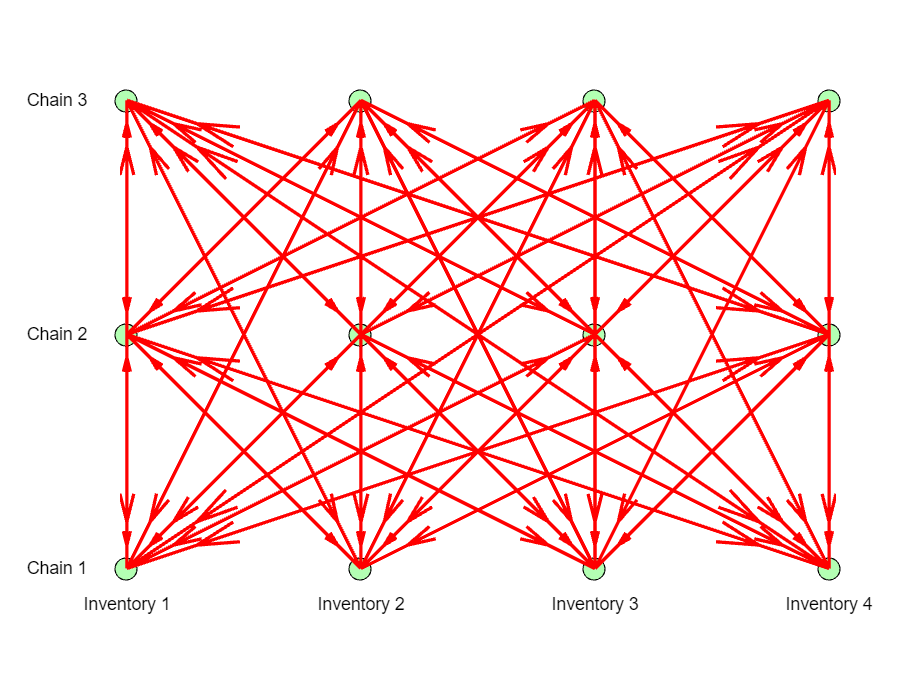


% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

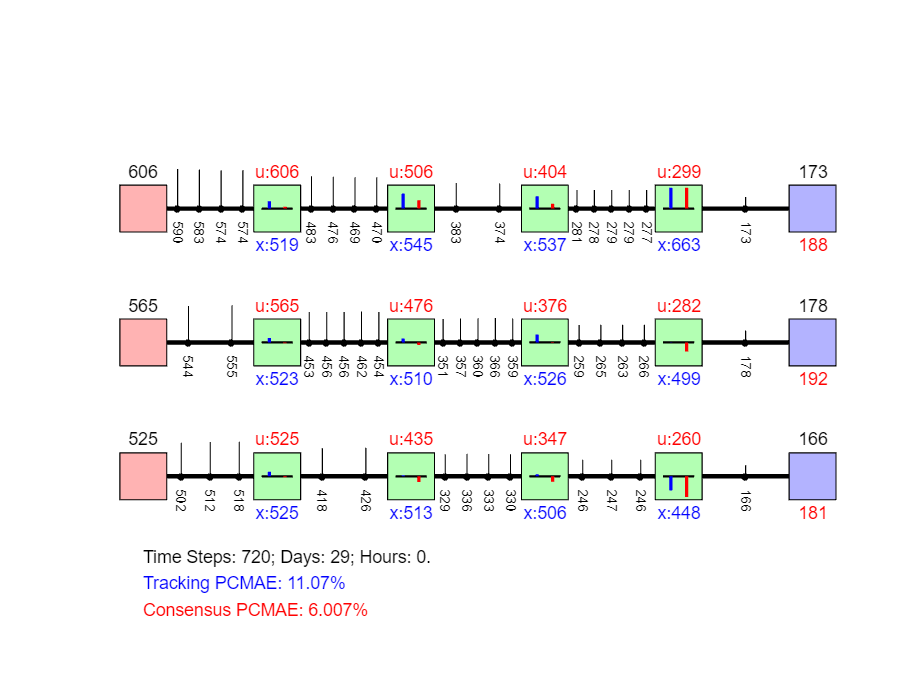


% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % % Performance plot
    figNum = figNum + 1;
    f = figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
    close(f);
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'DSC';
save('caseNum.mat','caseNum','perfData')

% perfData.cumVals
% What are the inventory capacities that will not limit controllers?
% How to improve tracking error performance without compromizing consensus
% error performance? - Change the local controller design approach....
% Local controllers being overly strong might be causing the osillatory
% behavior, - high control inputs causing overshoots...
% Is there an additional condition on KGlobal for conesensus_tracking
% (e.g., K*1 = 0?, read consensus notes/discussion)

Summary Plots (for the paper)

% A = [40.4448	26.9191; 34.4617	22.8563]
perfData.cumVals

ans =    41.9973   29.3427
   38.6971   23.5051
   55.3479   30.0063
   55.3647   30.0340


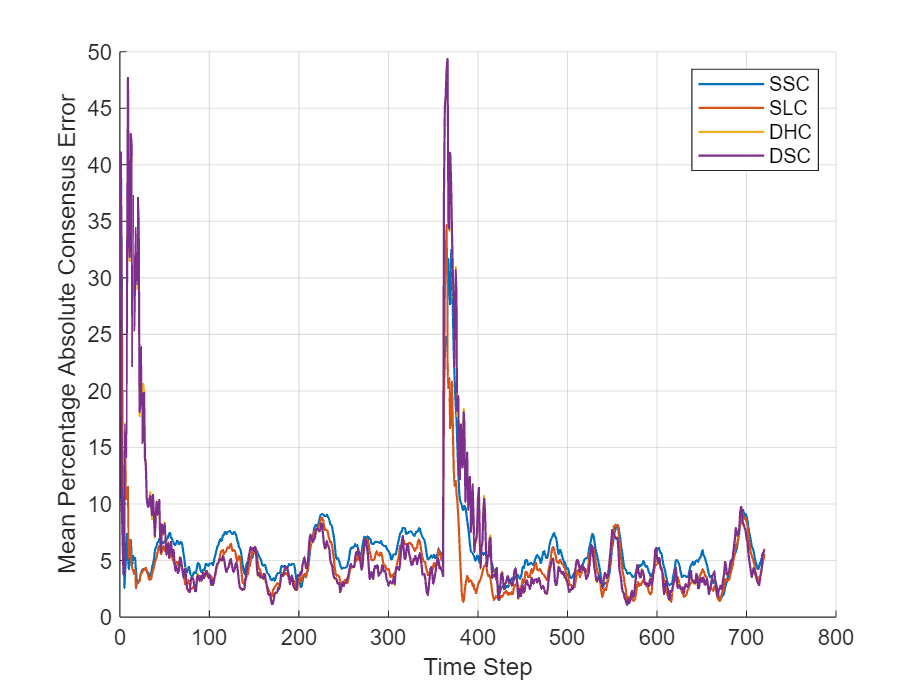


close all
clc

conHist = perfData.conHist;
traHist = perfData.traHist;
caseNames = perfData.caseName;
numCases = size(conHist,1);

L = size(conHist,2);

figNum = figNum + 1;
figure(figNum);
hold on; grid on;
for k = 1:numCases
    plot(1:L, conHist(k,:), '-', 'LineWidth', 1, 'DisplayName', caseNames{k+1});
    % title(sprintf('Performance Metrics at Time Step %d', t));
    xlabel('Time Step');
    ylabel('Mean Percentage Absolute Consensus Error');
    legend('Location', 'northeast');   
end

percentageImprovement = sum(conHist(end-1,:)>=conHist(end,:))*100/L

percentageImprovement = 48.4722

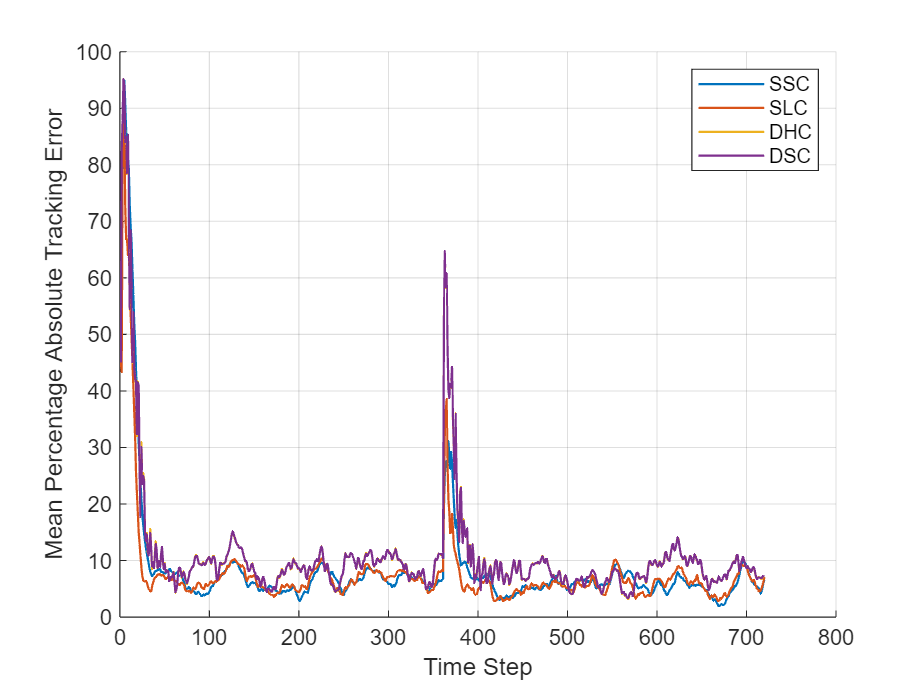


figNum = figNum + 1;
figure(figNum);
hold on; grid on;
for k = 1:numCases
    plot(1:L, traHist(k,:), '-', 'LineWidth', 1, 'DisplayName', caseNames{k+1});
    % title(sprintf('Performance Metrics at Time Step %d', t));
    xlabel('Time Step');
    ylabel('Mean Percentage Absolute Tracking Error');
    legend('Location', 'northeast');   
end

percentageImprovement = sum(traHist(end-1,:)>=traHist(end,:))*100/L

percentageImprovement = 48.8889



% net.printDefaultProperties()